# fun_callTraj

## *Bahnplanung:*

Diese Funktion berechnet den Verlauf von einer aktuellen Position TCPs (Tool Center Point) (px, py) um zu einer gegebenen Zielposition (px,ziel, py,ziel) des TCPs zu gelangen. Hierfür wird der Algorithmus 2 (abb.1) verwendet. Die Schrittweite beträgt δt=  10 ms. Kann der Verlauf der Bahn nicht abgefahren werden, erfolgt eine Ausgabe einer Fehlermeldung und eine Variation der Parameter ̄a und ̄vi werden solange geändert bis diese eine gültige Bahn erhält. Es wird mit folgenden Werten : ̄v1=  ̄v2= 100`◦/`s und  ̄a= 5`◦/`s`2 `gestartet.

### Algorthmus 2:

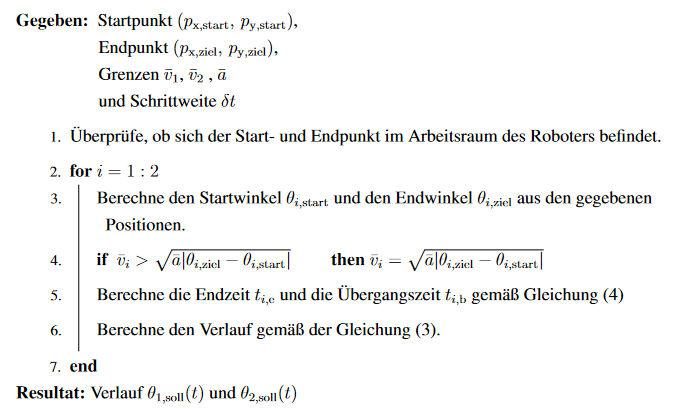

*Abb.1: Verlaufberechnung Algorithmus 2 *

Übergabewerte:

- Ist-Position px und py und Ziel-Position px,ziel und py,ziel

Rückgabewerte:

- Soll-Verläufe der Winkel θ1,soll(t) und θ2,soll(t) in Gradmaß

    Erläuterung zum Rückgabewert:

- `    theta_soll1(:,1)`:             Zeitwerte t für den Verlauf von θ1,soll(t)

- `    theta_soll1(:,2)`:             Berechnete Winkelwerteθ1,

-         soll(t)`theta_soll2(:,1)`:    Zeitwerte t für den Verlauf von θ2,

-         soll(t)`theta_soll2(:,2)`:    Berechneten Winkelwerte θ2,soll(t)

Aufruf: 

Beispiel:

### Autor: Paul Freynik Matr.Nr. 2017507935

  % Start der Funktion
  function [theta1_soll,theta2_soll] = fun_callTraj(px_start,py_start,px_ziel,py_ziel)
        % Beschleunigungsgrenze Startwerte
        a = 5; 
        % Geschwindigkeitsbegrenzung Startwerte
        v = [100,100];
        % Schrittweite
        delta_t = 0.01;

    

#### 1. Überprüfung, ob sich der Start- und Endpunkt im Arbeitsraum des Roboters befindet.

#### 2. und 3. Berechne den Startwinkel θi,start und den Endwinkel θi,ziel aus den gegebenenPositionen.

    
% Startbedingungen überprüfen
  % Berechne den Startwinkel θi,start und den Endwinkel θi,ziel
  % aus den gegebenen Positionen
    % if-Schleife Vergleich Arbeitsbereich
    if ~fun_checkWorkspace(px_start,py_start) || ~fun_checkWorkspace(px_ziel,py_ziel)
        % Ausgabe Fehlermeldung
        disp("error start oder zielpunkt liegen auserhalb des arbeitsbereichs!")
        % Initialisierung Sollwert
        theta1_soll= 0;
        % Initialisierung Sollwert
        theta2_soll = 0;
        % Ausgabe
        return;
    % Ende if Schleife Zeile 16    
    end     
    
    % for Schleife
    for i = 1:2
      % Start und Endwinkel berechnen
        % Startwerte berechnen
        [theta_start(1),theta_start(2)] = fun_callInvKin(px_start,py_start);
        % Zielwerte berechnen
        [theta_ziel(1),theta_ziel(2)] = fun_callInvKin(px_ziel,py_ziel);
   
    

### Gleichung Beschleunigungsbegrenzung Abb.2:

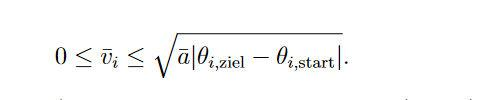

*Abb.2: Gleichung zur Berechnung Beschleunigungsbegrenzung*

#### 4. Setzen der Beschleunigungsbegrenzung

        
      % setzen der Beschleunigungsbegrenzung
        % Berechnung
        agrenz = sqrt(a*abs(theta_ziel(i)-theta_start(i)));
        % if Schleife
        if v(i) > agrenz
            % Ersetzen der Beschleunigungsbegrenzung
            v(i) = agrenz;
        % Ende if Schleife Zeile 42
        end     
  

### ***Gleichung zur Berechnung der***** Endzeit ti,e und der Übergangszeit ti,b gemäß Gleichung Abb.4:**

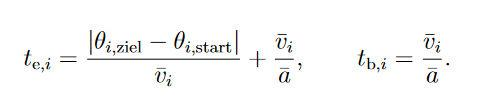

*Abb.4: Gleichung zur Berechnung der* Endzeit ti,e und der Übergangszeit ti,b.

#### 5. Berechnung der Endzeit ti,e und die Übergangszeit ti,b gemäß Gleichung (Abb.4)


      % Berechnen der Endzeit te und Übergangszeit tb
        % Berechnung der Übergangszeit
        tb = v(i)/a;
        % Berechnung der Endzeit
        te = abs(theta_ziel(i)-theta_start(i))/v(i) + v(i) / a;
        % Bestimmung der Schrittmenge
        te(isnan(te))=0;
        time = 0:delta_t:te;
        % Erstellen einer Matrix mit nullen
        thetasoll = zeros(1,length(time));
        

### Rechenvorschrift asynchronen PTP-Bahn:

Die Winkelverläufe berechnen sich bei der asynchronen PTP-Bahn unabhängig von einander. Die Rechenvorschrift (Abb. 3) lautet wie folgt:

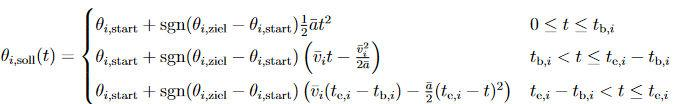

*Abb.3: Rechenvorschrift*

#### 6. Berechnung des Verlaufs gemäß der Gleichung (Abb.3)

        
      % Verlaufsberechnung
        % for Schleife
        for j = 1:length(time)
            % Zeitwert
            t = time(j);
            % if-Schleife
            if 0 <= t  && t <= tb
                % Verlaufsberechnung
                thetasoll(j) = theta_start(i) + sign(theta_ziel(i) ...
                    -theta_start(i))*((1/2)*a*t^2);
            % elseif-Bedingung
            elseif  tb < t  && t <= (te - tb)
                % Verlaufsberechnung
                thetasoll(j) = theta_start(i) + sign(theta_ziel(i) ...
                    -theta_start(i))*((v(i)*t)-(v(i)^2)/(2*a));
            % elseif-Bedingung
            elseif  (te - tb)  < t && t <= te 
                % Verlaufsbedingung
                thetasoll(j) = theta_start(i) + sign(theta_ziel(i) ...
                     -theta_start(i))*(v(i)*(te-tb)-(a/2)*(te-t)^2);
            % Ende if-Schleife Zeile 66
            end
        % Ende for-Schleife Zeile 62 
        end
        

#### Resultat: Verlauf θ1,soll(t) und θ2,soll(t)

        
      % Werte speichern und zurückgeben
        % if Schleife
        if i == 1
            % Rückgabewert Winkelwert
            theta1_soll = [time(:),thetasoll(:)];
        else    % else Bedingung
            % Rückgabewert Winkelwert
            theta2_soll = [time(:),thetasoll(:)];
        % Ende if Schleife Zeile 88
        end
    % Ende for Schleife Zeile 29
    end     
% Ende Funktion Zeile 2    
end     
